**Fitting Polynomials to Data Manually**

In order to fit a polynomial to a data set, there's a few things you need.

First, your data set must have at least 3 points, we'll be working through an example first. 

Consider a data set with 3 points (x,y) at (0, 0), (1.5, 1.5), and (4, 1)

DataPoints = [0,0; 1.5,1.5;4,1]
figure();
scatter(DataPoints(:,1),DataPoints(:,2), 30, 'r',"filled");xlabel('x');ylabel('y');

We want to find a polynomial function that passes through all these points. The most direct way to do this will be with an Nth order polynomial, where N is 1 less than the number of points we wish to pass through; In this case, it will be a 2nd order polynomial (quadratic) since we have 3 points to pass through. The polynomial that we find should take the form: 


$$f\left(x\right)=a_0 +a_1 x+a_2 x^2 +\;\ldotp \ldotp \ldotp \;a_N x^N$$


Where N is the degree of the polynomial and 1 less than the number of points we are trying to fit and each a is a coefficient.

The first step to fit the polynomial is to write out the polynomial at each of the N+1 points:


$$f\left(x_1 \right)=a_0 +a_1 x_1 +a_2 {x_1 }^2 +\;\ldotp \ldotp \ldotp \;a_N {x_1 }^N$$



$$f\left(x_2 \right)=a_0 +a_1 x_2 +a_2 {x_2 }^2 +\;\ldotp \ldotp \ldotp \;a_N {x_2 }^N$$



$$f\left(x_3 \right)=a_0 +a_1 x_3 +a_2 {x_3 }^2 +\;\ldotp \ldotp \ldotp \;a_N {x_3 }^N$$


We can represent this in MATLAB through the use of matrices and vectors


$$\left\lbrack \begin{array}{c}
f\left(x_1 \right)\\
f\left(x_2 \right)\\
f\left(x_3 \right)\\
\ldotp \ldotp \ldotp \\
f\left(x_{N+1} \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
1 & x_1  & x_1^2  &  & x_1^N \\
1 & x_2  & x_2^2  & \ldotp \ldotp \ldotp  & x_2^N \\
1 & x_3  & x_3^2  &  & x_3^N \\
 & \ldotp \ldotp \ldotp  &  & \ldotp \ldotp \ldotp  & \\
1 & x_{N+1}  & x_{N+1}^2  &  & x_{N+1}^N 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\ldotp \ldotp \ldotp \\
a_N 
\end{array}\right\rbrack$$


This can be written more simply as:


$$\left\lbrack f\right\rbrack =\left\lbrack X\right\rbrack \left\lbrack a\right\rbrack$$


or


$$\left\lbrack X\right\rbrack \left\lbrack a\right\rbrack =\left\lbrack f\right\rbrack$$


We can now solve for [a] in order to find our polynomial coefficients.


$$\begin{array}{l}
\left\lbrack a\right\rbrack ={\left\lbrack X\right\rbrack }^{-1} \left\lbrack f\right\rbrack \\
\left\lbrack a\right\rbrack =\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\ldotp \ldotp \ldotp \\
a_N 
\end{array}\right\rbrack 
\end{array}$$


Let's do that for our example data:

x_Coords = DataPoints(:,1);
f = DataPoints(:,2)
X = [1, x_Coords(1), x_Coords(1)^2;
     1, x_Coords(2), x_Coords(2)^2;
     1, x_Coords(3), x_Coords(3)^2]
a = X\f

Once we have our a coefficients, we just write the polynomial in the form we determined earlier and we have our function! 


$$f\left(x\right)=a_0 +a_1 x+a_2 x^2 +\;\ldotp \ldotp \ldotp \;a_N x^N$$


Note that the coefficients in $a$ are in order of increasing degree, so to be able to use the polyval function, we will have to flip the order of $a$.

x_Range = linspace(0,4,50);
ApproxFunc = polyval(flip(a),x_Range);
disp('f(x) = 0 + 1.45x - .3x^2')
% We can then plot this against our data to verify that everything fits
% correctly.
figure();
hold on
plot(x_Range,ApproxFunc);
scatter(DataPoints(:,1),DataPoints(:,2), 30, 'r',"filled");xlabel('x');ylabel('y');
hold off
% Fit looks Good!

**Fitting using MATLAB**

This is all well and good but it can take a long time for large sets of data. Thankfully, MATLAB has the polyfit function that will allow us to do this faster. The syntax for the polyfit function is as follows:

Coefficients = polyfit(x, y, n)

Where:

 x is a vector containing the independent data points (the x coordinate of your data points)

y is a vector containing the dependent data points (the y coordinate of your data points; must be the same size as x)

n is a scalar quantity that denotes the degree of your desired polynomial

Coefficients will be a vector of size n+1 and will contain the polynomial coefficients in order of DECREASING degree ($\left.x^3 ,x^2 ,x,\textrm{etc}\ldotp \right)$

Let's give the polyfit function a try with the same data we had previously:

DataPoints = [0,0; 1.5,1.5;4,1]
x_Coords = DataPoints(:,1);
y_Coords = DataPoints(:,2);
x_Range = 0:.1:max(x_Coords)
% We can notably choose whatever degree we want for the polyfit function,
% let's choose 2 this time for the sake of simplicity.
Coefficients = polyfit(x_Coords,y_Coords,2)
% These are the same coefficients we received earlier, albeit in a different
% order. This arrangement is generally better since it is the standard way
% in which polynomial functions are written.

We can now take these coefficients and use the polyval function to generate a polynomial that we can graph:

FittedLine = polyval(Coefficients,x_Range)
figure()
hold on
plot(x_Range, FittedLine, 'b-', 'LineWidth', 2);
scatter(DataPoints(:,1),DataPoints(:,2), 30, 'r',"filled");xlabel('x');ylabel('y');
legend('Approximation', 'Data Points');title('Data Points and Polynomial Fit');
grid on;
hold off

This looks good, exactly what we had earlier. 

**Overfitting**

When using the polyfit function, it's important to make sure we pick a proper order of polynomial to ensure we don't overfit, as this can result in inaccurate approximations. Below is an example of overfitting:

DataPoints = [0,0; 1.5,1.5;4,1];
x_Coords = DataPoints(:,1);
y_Coords = DataPoints(:,2);
x_Range = 0:.1:max(x_Coords);
Coefficients = polyfit(x_Coords,y_Coords,2);
FittedLine = polyval(Coefficients,x_Range);
Overco1 = polyfit(x_Coords,y_Coords,3);

MATLAB will warn you if the polynomial is non-unique, which could indicate that you are overfitting 

Overfit1 = polyval(Overco1,x_Range);
Overco2 = polyfit(x_Coords,y_Coords,4);
Overfit2 = polyval(Overco2,x_Range);
Overco3 = polyfit(x_Coords,y_Coords,5);
Overfit3 = polyval(Overco3,x_Range);

figure()
hold on
plot(x_Range, FittedLine, 'b-', 'LineWidth', 2);
plot(x_Range, Overfit1, 'c-', 'LineWidth', 2);
plot(x_Range, Overfit2, 'g-', 'LineWidth', 2);
plot(x_Range, Overfit3, 'y-', 'LineWidth', 2);
scatter(DataPoints(:,1),DataPoints(:,2), 30, 'r',"filled")
legend('Approximation', '3rd Degree Overfit', '4th Degree Overfit', '5th Degree Overfit','Data Points','Location','northwest');
title('Data Points and Polynomial Overfitting');
xlabel('x')
ylabel('y')
grid on;
hold off

As you can see, the overfitted lines are still able to pass through all the points, but the overall paths they follow don't seem to make much sense and get increasingly more erratic as the polynomial degree increases. 

**Extrapolation and Interpolation**

Interpolation is when you are looking to solve for values that are between measured values

Extrapolation is when you are looking to solve for values outside of the domain established by your measured values

Extrapolation and Interpolation are used when taking new measurements is difficult or inefficient.

**Linear Interpolation**

Given two data points, a line can be fit from which it is possible to interpolate or extrapolate any other points. 

Given two data points (x1,y1) and (x2,y2) the equation for such a line is


$$y-y_1 =\frac{y_2 -y_1 }{x_2 -x_1 }\left(x-x_1 \right)$$


This equation can then be used to interpolate any $y_i$ from any desired position $x_1$.


$$y_i =y_1 +\frac{y_2 -y_1 }{x_2 -x_1 }\left(x_i -x_1 \right)$$


Data curves are not always linear though, and if the distance between the two points is too great (or your extrapolation is too far removed from your points), you can end up with a great deal of error that can invalidate your approximation

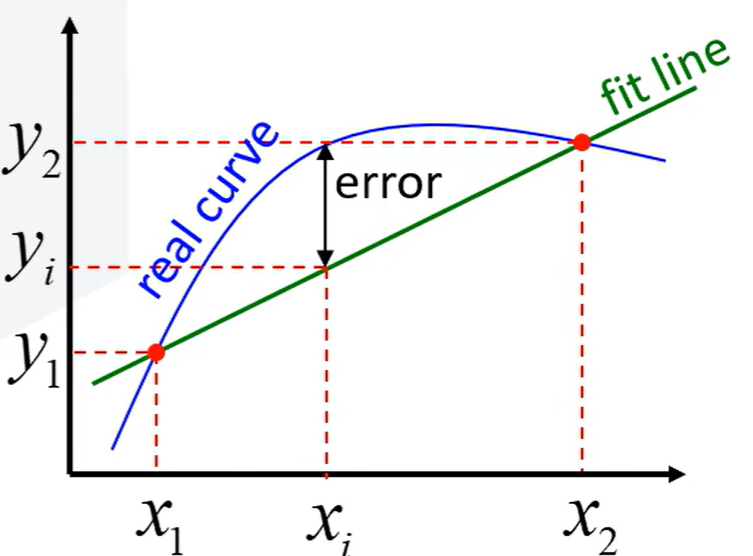

A way to reduce this error is to instead use polynomial interpolation, which we will cover next; working once again with our same points:

**Given the data points:**

f(0) = 0

f(1.5) = 1.5

f(4) = 1

**Interpolate f(3) and extrapolate f(5)**

DataPoints = [0,0; 1.5,1.5;4,1];
x_Coords = DataPoints(:,1);
y_Coords = DataPoints(:,2);
x_Range = 0:.1:max(x_Coords) + 2;

Recall that we have already used the polyfit function on this set of data and found a 2nd degree polynomial that passes through all the data, so we can just reuse our code, making a slight modification to turn our Fitted line into an anonymous function to allow us to evaluate it at any point

Coefficients = polyfit(x_Coords,y_Coords,2);
FittedLine = @(x) polyval(Coefficients,x);
Interpolation = FittedLine(3)
Extrapolation = FittedLine(5)

y_Range = FittedLine(x_Range);

figure()
hold on
plot(x_Range, y_Range, 'b-', 'LineWidth', 2);
scatter(DataPoints(:,1),DataPoints(:,2), 30, 'r',"filled")
scatter(3,Interpolation, 30, 'g',"filled")
scatter(5,Extrapolation, 30, 'y',"filled")
legend('Approximation','Data Points', 'Interpolation at 3', 'Extrapolation at 5', 'Location','southwest');
title('Data Points and Polynomial Overfitting');xlabel('x');ylabel('y');
grid on;
hold off

And just like that, we can take a set of data points, create a function to represent them, and use that function to extrapolate new points!

## **Exercise: CVT Torque Calibration**

Now that you know how to fit a polynomial to data and extrapolate new information, give it a try down below on this new set of data. Feel free to reference earlier work or the internet if you need.

*Disclaimer*: These numbers are not actually representative of real data, I just added the Baja context to show potential applications for these skills, feel free to ignore the context if it's causing difficulty.

% The arrays `RPM_Scaled` and `Torque_out` contain test bench measurements 
% from the Baja car's Continuous Variable Transmission (CVT) system. 
% Your task is to fit a quadratic curve (2nd Degree) to this data to create 
% a predictive mathematical model for the torque output.

RPM_Scaled = [1, 2, 3, 4, 5];
Torque_Out = [2, 5, 10, 17, 26];

% TASK 1: 
% Use the polyfit function to find the coefficients of a 2nd Degree 
% polynomial that best fits the data above. 
% Assign the resulting vector to a variable named 'CVT_Coeffs'.

CVT_Coeffs = % YOUR CODE HERE

% TASK 2: 
% A new test run had the engine operating at a scaled RPM of 3.5. 
% Use the polyval function and your newly created 'CVT_Coeffs' model 
% to estimate the output torque at this specific RPM. 
% Assign the result to a variable named 'Estimated_Torque'.

Target_RPM = 3.5;
Estimated_Torque = % YOUR CODE HERE

% TASK 3:
% Let's visualize the fit! First, create a dense array of RPM values 
% to plot a perfectly smooth curve. 
% 1. Create a vector of 100 points between 1 and 5 and name it 'RPM_Range'.
% 2. Evaluate your 'CVT_Coeffs' model over 'rpm_fine' and name it 'Torque_Range'.
% 3. Plot the original data points as circles, and the fitted curve as a solid line.
%    (Don't forget to add a legend, title, and axis labels!)

RPM_Range = % YOUR CODE HERE
Torque_Range = % YOUR CODE HERE

% YOUR PLOTTING CODE HERE:

% =========================================================================
% --- DO NOT MODIFY BELOW THIS LINE ---
% Assertion Tests
% Run this section to verify your answers. If you do not see any red error 
% text, your code is correct!
% =========================================================================

assert(exist('CVT_Coeffs', 'var') == 1, 'Variable CVT_Coeffs does not exist. Did you name it correctly?');
assert(length(CVT_Coeffs) == 3, 'CVT_Coeffs should have exactly 3 elements for a 2nd-degree polynomial.');
assert(abs(CVT_Coeffs(1) - 1) < 1e-4, 'Your polynomial coefficients appear incorrect. Double-check your polyfit inputs and the specified degree.');

assert(exist('Estimated_Torque', 'var') == 1, 'Variable Estimated_Torque does not exist. Did you name it correctly?');
assert(abs(Estimated_Torque - 13.25) < 1e-4, 'Your estimated torque is incorrect. Double-check how you are using polyval with the Target_RPM.');

disp('All tests passed! Excellent work.')